# `getDataTips()`** examples and use cases**

**Examples of **`getDataTips()`**, used to extract data tip content and handles.**

Source: [getDataTips on the file exchange](https://www.mathworks.com/matlabcentral/fileexchange/82038-getdatatips-get-data-tip-text-and-handles)

Author: [Adam Danz](https://www.mathworks.com/matlabcentral/profile/authors/3753776)

Version: 1.0.1

This example file requires Matlab r2019b or later.  

## Set up two example figures with data tips

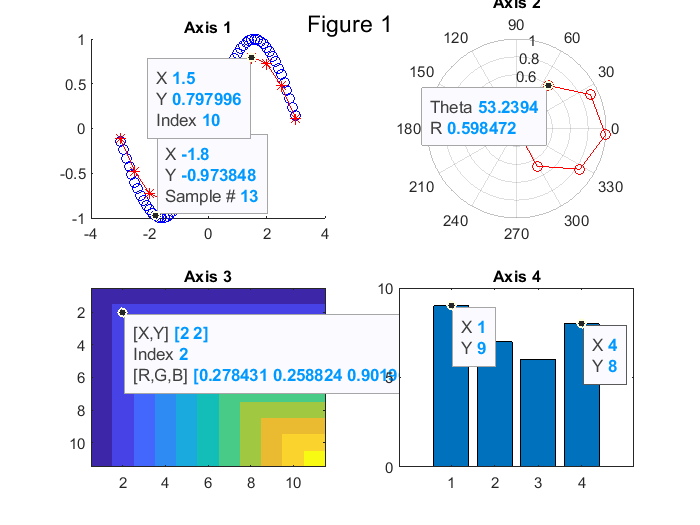

fig1 = figure('Name', 'Example figure 1');
h(1) = subplot(2,2,1);
hold(h(1),'on')
p{1} = scatter(-3:.1:3, sin(-3:.1:3),'bo');
p{2} = plot(-3:.5:3, sin(-3:.5:3)*.8,'r*-');
title('Axis 1')

h(2) = subplot(2,2,2,polaraxes);
p{3} = polarplot(h(2),-pi/2:.5:pi/2, cos(-pi/2:.5:pi/2),'-or');
title('Axis 2')

h(3) = subplot(2,2,3);
p{4} = imagesc(gallery('minij',11));
title('Axis 3')

h(4) = subplot(2,2,4);
p{5} = bar([9,7,6,8]);
title('Axis 4')

% Add some content to data tips in subplot 1
p{1}.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow('Sample #',1:numel(p{1}.XData));
p{2}.DataTipTemplate.DataTipRows(end+1) = dataTipTextRow('Index',1:numel(p{2}.XData));

% Place data tips; datatip() requires Matlab r2019b. 
datatip(p{1}, -1.8, sin(-1.8));
datatip(p{2}, 1.5, sin(1.5));
datatip(p{3}, -pi/2, sin(-pi/2));
datatip(p{4},2,2);
datatip(p{5},1,9);
datatip(p{5},4,8);

sgtitle('Figure 1')

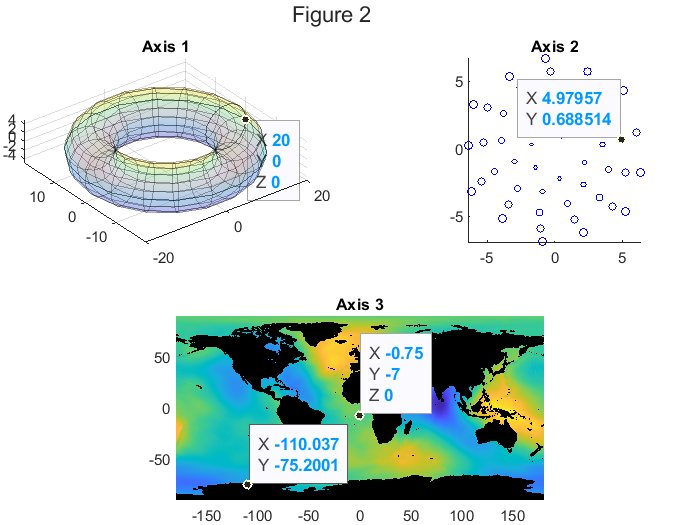

fig2 = figure('Name','Example figure 2');
tiledlayout(2,2,'Padding','none')
hh(1) = nexttile(); 
R=20; r=5;
[a, b] = meshgrid(0:20/180*pi:2*pi);
X=((R-r)+r*cos(a)).*cos(b);
Y=((R-r)+r*cos(a)).*sin(b);
Z=r.*sin(a);
pp{1} = surf(X,Y,Z,'FaceColor','interp','FaceAlpha',0.2,'EdgeAlpha',0.3);
axis equal; 
title('Axis 1')

hh(2) = nexttile();
theta = 1:2*pi/(sqrt(5)+1)/2:50;
r = sqrt(theta);
[x,y] = pol2cart(theta,r);
msize = (r-min(r))/range(r)*24+1;
pp{2} = scatter(x,y,msize,'b','Marker', 'o');
axis equal; axis tight
title('Axis 2')

hh(3) = nexttile([1,2]);
[N,R] = egm96geoid;
Z = zeros(R.RasterSize);
pp{3} = geoshow(N,R,'DisplayType','surface','CData',N,'ZData',Z);
pp{4} = geoshow('landareas.shp','FaceColor','black');
title('Axis 3')
axis tight

% Place data tips
datatip(pp{1});
datatip(pp{2}, pp{2}.XData(26), pp{2}.YData(26));
datatip(pp{3}, pp{2}.XData(50), pp{2}.YData(50));
datatip(pp{4}.Children(1), -110.04, -75.2);

sgtitle('Figure 2')

## Print data tip content 

### Syntax: `getDataTips()`

When no outputs are requested in `getDataTips`, the data tip content is printed to the command window or within the live script. 

When there are no inputs, `getDataTips` searches the current figure (`gcf`) which is figure 2 in this example. 

getDataTips()

Data tips found in  Figure 2:
   X -0.75   
   Y -7      
   Z 0       
   ------    
   X 4.97957 
   Y 0.688514
   ------    
   X 20      
   Y 0       
   Z 0       
   ------    
   X -110.037
   Y -75.2001
   ------    


### Syntax: `getDataTips(h)`

Specify which figure or axes to search.

getDataTips(fig1)

Data tips found in  Figure 1:
   X 4                                 
   Y 8                                 
   ------                              
   X 1                                 
   Y 9                                 
   ------                              
   [X,Y] [2 2]                         
   Index 2                             
   [R,G,B] [0.278431 0.258824 0.901961]
   ------                              
   Theta 53.2394                       
   R 0.598472                          
   ------                              
   X 1.5                               
   Y 0.797996                          
   Index 10                            
   ------                              
   X -1.8                              
   Y -0.973848                         
   Sample # 13                         
   ------                              


The first input can also be an array of figure or axis handles.  This example prints the data tips in the first and third axes in figure 1 and the second axis in figure 2.

getDataTips([h([1,3]),hh(2)])

Data tips found in specified axes within Figure 1:
   X 1.5      
   Y 0.797996 
   Index 10   
   ------     
   X -1.8     
   Y -0.973848
   Sample # 13
   ------     
Data tips found in specified axes within Figure 1:
   [X,Y] [2 2]                         
   Index 2                             
   [R,G,B] [0.278431 0.258824 0.901961]
   ------                              
Data tips found in specified axes within Figure 2:
   X 4.97957 
   Y 0.688514
   ------    


This example prints the data tips in both figures.

getDataTips([fig1,fig2])

Data tips found in  Figure 1:
   X 4                                 
   Y 8                                 
   ------                              
   X 1                                 
   Y 9                                 
   ------                              
   [X,Y] [2 2]                         
   Index 2                             
   [R,G,B] [0.278431 0.258824 0.901961]
   ------                              
   Theta 53.2394                       
   R 0.598472                          
   ------                              
   X 1.5                               
   Y 0.797996                          
   Index 10                            
   ------                              
   X -1.8                              
   Y -0.973848                         
   Sample # 13                         
   ------                              
Data tips found in  Figure 2:
   X -0.75   
   Y -7      
   Z 0

## Store DataTip content

When outputs are included the data tip content will *not* be printed.  

### Syntax: `content=getDataTips()`

Content from all data tips in the current figure (`gcf`) will be stored in a cell array.

content = getDataTips()

content = 1×1 cell array
    {4×1 cell}

`content` is a 1x1 cell array because the default value for input 1 is `gcf` which returns 1 figure handle.

content{1}

ans = 4×1 cell array
    {3×1 cell}
    {2×1 cell}
    {3×1 cell}
    {2×1 cell}

`content{1}` contains a 4x1 cell array because there are 4 data tips in the current figure. The size of each of these cells indicates the number of rows of text within each data tip.  For example, `size(content{1}{3})` returns `[3,1]` because the third data tip has 3 rows of text.

content{1}{3}

ans = 3×1 cell array
    {'X 20'}
    {'Y 0' }
    {'Z 0' }

### Syntax: `content=getDataTips(h)`

When an array of figure/axis handles are specified in `h`, `content` will return a cell array the same size as `h` containing data tip content for each handle.  

For example, the input below is a 1x3 array containing two axis handles and a figure handle.  

targets = [h([1,4]), fig2];  % [1x3] array
content = getDataTips(targets)

content = 1×3 cell array
    {2×1 cell}    {2×1 cell}    {4×1 cell}

The size of `content{i}` indicates the number of data tips within object `targets(i)`.  For example, `size(content{3})` returns `[4,1]` which indicates that there are 4 data tips in object `h(3)`.

content{3}

ans = 4×1 cell array
    {3×1 cell}
    {2×1 cell}
    {3×1 cell}
    {2×1 cell}

The size of `content{i}{j}` indicates the number of lines of text in data tip `j` of figure or axis `k`.  For example, `size(content{i}{j})` returns` [3,1]` which indicates that there are 3 rows of text in data tip `j`.

content{3}{1}

ans = 3×1 cell array
    {'X -0.75'}
    {'Y -7'   }
    {'Z 0'    }

Access the `k`-th row of text in data tip `j` of axis/figure `i` using `content{i}{j}{k}`

content{3}{1}{1}

ans = 'X -0.75'

## Set content output format

Setting the second input to `getDataTip` to `'char'` changes the data tip content from cell strings to character arrays. 

### Syntax: `content=getDataTips(h,'char')`

Using the same inputs as the example above, 

targets = [h([1,4]), fig2]; % [1x3] array
content = getDataTips(targets, 'char')

content = 1×3 cell array
    {2×1 cell}    {2×1 cell}    {4×1 cell}

`conent` is a cell array the same size and shape as the input array of figure/axis handles. 

content{1}

ans = 2×1 cell array
    {3×10 char}
    {3×11 char}

`content{1}` contains a 2x1 cell array because there are 2 data tips in axis `targets(1)`. 

`content{i}{j}` is a character array containing the text within the `j`-th data tip within the `i`-th handle. For example, to access the content of data tip 1 in the third figure/axis handle, 

content{3}{1}

ans = 3×7 char array
    'X -0.75'
    'Y -7   '
    'Z 0    '

## Get the data tip handles

The second output to `getDataTips` return handles to the data tips.

###  Syntax: `[~,dtHandle]=getDataTips(___)`

`dtHandle` is a cell array of data tip handles the same size as the first input and first output.

[content,dtHandle]=getDataTips(fig1)

content = 1×1 cell array
    {6×1 cell}

dtHandle = 1×1 cell array
    {6×2 Graphics}

`dtHandle{i}` contains an `n`x2 array of data tip handles for n data tips in handle `i`.  

`dtHandle{i}(:,1)` contains `n` handles to the `n` `PointDataTip` objects in handle `i`.

`dtHandle{i}(:,2)` contains `n` handles to the `n` `DataTip` objects in handle `i`. Older releases of Matlab do not provide the `DataTip` handle and column 2 will contain graphics place holders intead. 

dtHandle{1}

ans =   6×2 graphics array:

    PointDataTip    DataTip     
    PointDataTip    DataTip     
    PointDataTip    DataTip     
    PointDataTip    DataTip     
    PointDataTip    DataTip     
    PointDataTip    DataTip     

dtHandle{1}(1,1)

ans =     PointDataTip

dtHandle{1}(1,2)

ans =   DataTip (X 4, Y 8) with properties:

    DataIndex: 4
     Location: 'southeast'
       Parent: [1×1 Bar]

  Show all properties

### Get|Set data tip properties

Get of set object properties by using the `get`/`set` functions.

dtHandle{1}(1,1).get

       BackgroundAlpha: 1
       BackgroundColor: 'none'
          BeingDeleted: off
            BusyAction: 'queue'
         ButtonDownFcn: ''
              Children: [0×0 GraphicsPlaceholder]
           ContextMenu: [1×1 ContextMenu]
            Controller: [1×1 matlab.graphics.shape.internal.PointDataTipController]
             CreateFcn: ''
            CurrentTip: on
                Cursor: [1×1 matlab.graphics.shape.internal.PointDataCursor]
            DataSource: [1×1 Bar]
          DataTipStyle: MarkerAndTip
             DeleteFcn: ''
             Draggable: on
             EdgeColor: [0.65 0.65 0.65]
             FontAngle: 'normal'
              FontName: 'Helvetica'
              FontSize: 10
             FontUnits: 'points'
            FontWeight: 'normal'
      HandleVisibility: 'off'
               HitTest: on
                  Host: [1×1 Bar]
           Interpolate: off
           Interpreter: 'tex'
         Interruptible: on
                Marker: 'o'
       MarkerEdge

dtHandle{1}(1,2).get

           BeingDeleted: off
             BusyAction: 'queue'
          ButtonDownFcn: ''
               Children: [0×0 GraphicsPlaceholder]
                Content: {2×1 cell}
            ContextMenu: [1×1 ContextMenu]
              CreateFcn: ''
              DataIndex: 4
              DeleteFcn: ''
              FontAngle: 'normal'
          FontAngleMode: 'auto'
               FontName: 'Helvetica'
           FontNameMode: 'auto'
               FontSize: 10
           FontSizeMode: 'auto'
       HandleVisibility: 'on'
                HitTest: on
    InterpolationFactor: 0
            Interpreter: 'tex'
        InterpreterMode: 'auto'
          Interruptible: on
               Location: 'southeast'
           LocationMode: 'auto'
                 Parent: [1×1 Bar]
          PickableParts: 'visible'
               Selected: off
     SelectionHighlight: on
       SnapToDataVertex: on
                    Tag: 'datatip'
                   Type: 'datatip'
               UserData: []
    

Change the color and size of the marker for the data tip in axis 1 of figure 2. 

[~,dtHandle]=getDataTips(hh);
dtHandle{1}(1,1).MarkerSize = 12; 
dtHandle{1}(1,1).MarkerEdgeColor = 'k';
dtHandle{1}(1,1).MarkerFaceColor = [1 .6 0];

Change the background transparency and marker color of the data tips in axes 2 and 3 of figure 2.

[~,dtHandle]=getDataTips(hh(2:3));
all_dtHandles = vertcat(dtHandle{:}); 
set(all_dtHandles(:,1),'MarkerFaceColor',[1,0,0],'BackgroundAlpha',0.7);

Increase the font size of all data tips in figure 2.

[~,dtHandle]=getDataTips(fig2);
set(dtHandle{1}(:,1), 'FontSize', 15);

Change the position of the data tip if axis 1 of figure 2 so that it's southeast of the data tip marker and change the edge color. 

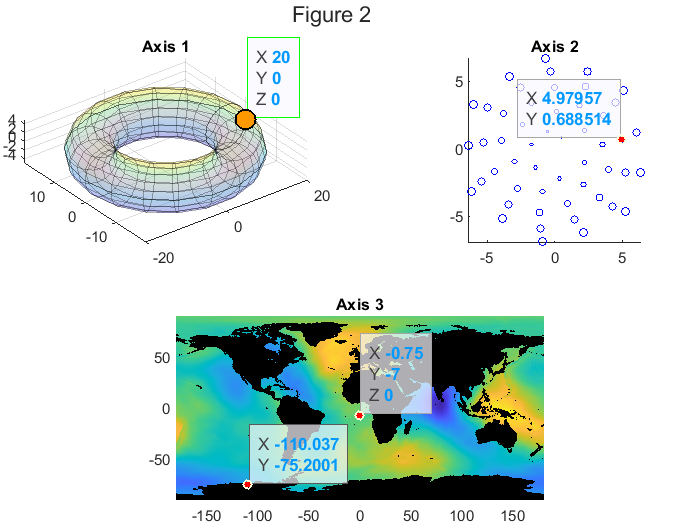

[~,dtHandle]=getDataTips(hh(1));
dtHandle{1}(1,2).Location = 'northeast';
dtHandle{1}(1,1).EdgeColor = 'g';